% datatable81 = unnamed;

Import data table and convert to array

load datatable.mat
data = table2array(datatable);

% p = data(:,1:4)';
% t = data(:,5:6)';
% 
% p1 = p(1,:);
% p2 = p(2,:);
% p3 = p(3,:);
% p4 = p(4,:);
% 
% t1 = t(1,:);
% t2 = t(2,:);
% 
% p1n = (data(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
% p2n = (data(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
% p3n = (data(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
% p4n = (data(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));
% t1n = (data(:,5)-min(data(:,5)))./(max(data(:,5))-min(data(:,5)));
% t2n = (data(:,6)-min(data(:,6)))./(max(data(:,6))-min(data(:,6)));
% 
% pn = [p1n p2n p3n p4n]';
% tn = [t1n t2n]';

%manual mapminmax for multi-target output
%[ttnn,ttss] = mapminmax(t)
%mapminmax('reverse',ttnn,ttss)

## hyperparameter optimization (number of neurons)

load datatable.mat
data = datatable81;
numdata = numel(data(:,1))

numdata = 81

foldsize = ceil(numdata/5);

%% randomize
randata = data(randperm(size(data,1)),:)

randata = 	1.0e+03 *

    0.0015    0.1400    0.5000    0.0050    0.0973    1.7097
    0.0020    0.1400    0.5000    0.0035    0.0765    1.6875
    0.0020    0.1200    0.3000    0.0035    0.0659    2.2039
    0.0010    0.1400    0.3000    0.0050    0.1398    1.6452
    0.0015    0.1200    0.5000    0.0035    0.0842    1.5322
    0.0015    0.1600    0.3000    0.0050    0.1104    1.3867
    0.0015    0.1200    0.5000    0.0020    0.0842    0.9508
    0.0015    0.1200    0.4000    0.0020    0.0845    0.8830
    0.0015    0.1400    0.4000    0.0035    0.0969    1.6488
    0.0015    0.1200    0.5000    0.0050    0.0814    1.8762


%% normalize
normdata = normalize(randata,"range");

fold1 = normdata(1:foldsize,:);
fold2 = normdata(foldsize+1:2*foldsize,:);
fold3 = normdata(2*foldsize+1:3*foldsize,:);
fold4 = normdata(3*foldsize+1:4*foldsize,:);
fold5 = normdata(4*foldsize+1:numdata,:);

f1 = [fold1;fold2;fold3;fold4;fold5]';
f2 = [fold2;fold1;fold3;fold4;fold5]';
f3 = [fold3;fold1;fold2;fold4;fold5]';
f4 = [fold4;fold1;fold2;fold3;fold5]';
f5 = [fold5;fold1;fold2;fold3;fold4]';

valInd = 1:foldsize;
trainInd = foldsize+1:numdata;

for i=1:50
Fcn = 'poslin';
netf1 = fitnet(i,'trainlm');
netf2 = fitnet(i,'trainlm');
netf3 = fitnet(i,'trainlm');
netf4 = fitnet(i,'trainlm');
netf5 = fitnet(i,'trainlm');

netf1.divideFcn = 'divideind';
netf1.divideParam.valInd = 1:foldsize;
netf1.divideParam.trainInd = foldsize+1:numdata;
netf1.inputs{1}.processFcns   = {'removeconstantrows'};
netf1.outputs{2}.processFcns  = {'removeconstantrows'};
netf1.layers{1}.transferFcn = Fcn;

netf2.divideFcn = 'divideind';
netf2.divideParam.valInd = 1:foldsize;
netf2.divideParam.trainInd = foldsize+1:numdata;
netf2.inputs{1}.processFcns   = {'removeconstantrows'};
netf2.outputs{2}.processFcns  = {'removeconstantrows'};
netf2.layers{1}.transferFcn = Fcn;

netf3.divideFcn = 'divideind';
netf3.divideParam.valInd = 1:foldsize;
netf3.divideParam.trainInd = foldsize+1:numdata;
netf3.inputs{1}.processFcns   = {'removeconstantrows'};
netf3.outputs{2}.processFcns  = {'removeconstantrows'};
netf3.layers{1}.transferFcn = Fcn;

netf4.divideFcn = 'divideind';
netf4.divideParam.valInd = 1:foldsize;
netf4.divideParam.trainInd = foldsize+1:numdata;
netf4.inputs{1}.processFcns   = {'removeconstantrows'};
netf4.outputs{2}.processFcns  = {'removeconstantrows'};
netf4.layers{1}.transferFcn = Fcn;

netf5.divideFcn = 'divideind';
netf5.divideParam.valInd = 1:foldsize;
netf5.divideParam.trainInd = foldsize+1:numdata;
netf5.inputs{1}.processFcns   = {'removeconstantrows'};
netf5.outputs{2}.processFcns  = {'removeconstantrows'};
netf5.layers{1}.transferFcn = Fcn;

[netf1,trf1] = train(netf1,f1(1:4,:),f1(5:6,:));
[netf2,trf2] = train(netf2,f2(1:4,:),f2(5:6,:));
[netf3,trf3] = train(netf3,f3(1:4,:),f3(5:6,:));
[netf4,trf4] = train(netf4,f4(1:4,:),f4(5:6,:));
[netf5,trf5] = train(netf5,f5(1:4,:),f5(5:6,:));
err(i) =(trf1.best_vperf+trf2.best_vperf+trf3.best_vperf+trf4.best_vperf+trf5.best_vperf)/5;
end

plot(err);
[M0,I0] = min(err);
disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

    23



disp('Which has MSE =')

Which has MSE =


disp(M0)

    0.0053



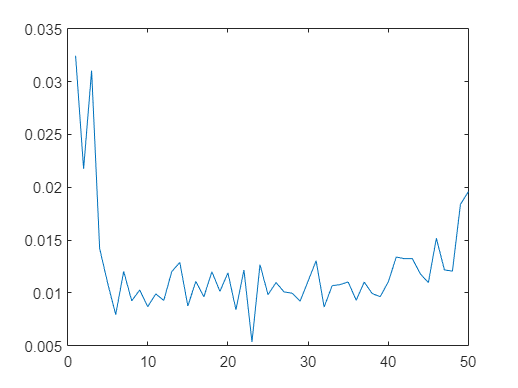

hold off;

for n=1:50                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net0.inputs{1}.processFcns   = {'removeconstantrows'};
net0.outputs{2}.processFcns  = {'removeconstantrows'};
net0.layers{1}.transferFcn = 'poslin';

[net0,tr0] = train(net0,pn,tn);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

net0 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input


plot(mse_val0,'-');

disp('training index of best MSE value set is')
disp(I0)
disp('Which has MSE =')
disp(M0)
hold off;

net1 = fitnet(15,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 15
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inpu

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net1.inputs{1}.processFcns   = {'removeconstantrows'};
net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'poslin';

input = normalize(datatable144(:,1:4),'range');
[net1,tr1] = train(net1,f1(1:4,:),f1(5:6,:));

output_ANN1 = net1(input')

output_ANN1 =     0.4879    0.4943    0.4884    0.4885    0.5023    0.5009    0.4969    0.5102    0.5112    0.6596    0.6697    0.6684    0.6626    0.6763    0.6828    0.6712    0.6843    0.6927    0.8319    0.8241    0.8223    0.8285    0.8337    0.8511    0.8359    0.8409    0.8466    0.9795    0.9671    0.9668    0.9784    0.9909    0.9993    0.9780    0.9853    0.9977    0.2918    0.2976    0.2879    0.2667    0.2695    0.2608    0.2614    0.2642    0.2610    0.3586    0.3788    0.3843    0.3627    0.3607
    0.0555    0.3866    0.6585    0.0251    0.3491    0.7329   -0.0084    0.3115    0.7303    0.0606    0.4994    0.6660    0.1004    0.4244    0.6691    0.0704    0.3868    0.7495    0.0622    0.5863    0.5862    0.1103    0.4431    0.5545    0.1170    0.4039    0.6519    0.0400    0.6350    0.5358    0.0314    0.4539    0.5036    0.1223    0.3820    0.5622    0.0690    0.4851    0.5803    0.1292    0.4565    0.6692    0.1110    0.4214    0.7765    0.0699    0.5915    0.5497    0

ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =    98.6338   99.4425   98.6926   98.7145  100.4450  100.2702   99.7620  101.4475  101.5662  120.2813  121.5516  121.3917  120.6592  122.3897  123.2033  121.7450  123.3922  124.4635  142.0161  141.0277  140.7965  141.5879  142.2328  144.4375  142.5169  143.1444  143.8684  160.6169  159.0571  159.0259  160.4820  162.0568  163.1243  160.4326  161.3573  162.9182   73.9082   74.6340   73.4150   70.7414   71.0930   69.9952   70.0773   70.4203   70.0227   82.3309   84.8736   85.5691   82.8473   82.5891


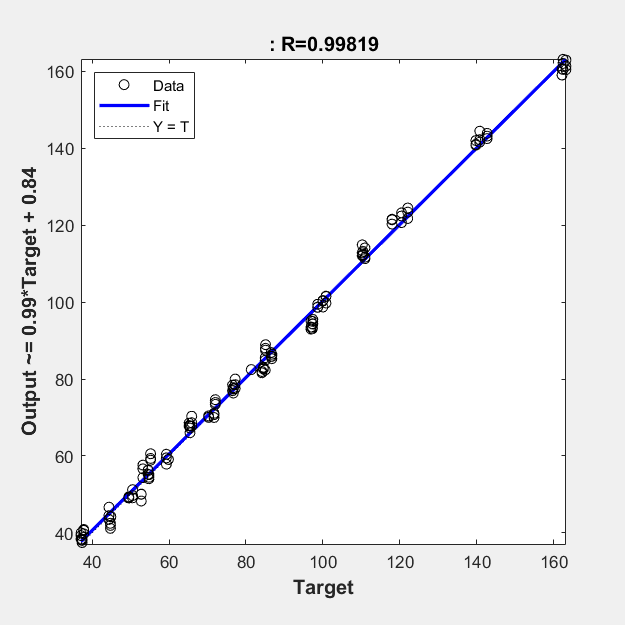

%ANNSEA = ((output_ANN1(1,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))
plotregression(datatable144(:,5),ANNIPF');

%plotregression(datatable144(:,6),ANNSEA');
% plotregression(t1n,output_ANN1(1,:));
% plotregression(t2n,output_ANN1(2,:));


pred = net1([0.75 0.75 0.75 0.75]')

pred = 0.5457


IPF = ((pred(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

IPF = 105.9218

SEA = ((pred(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

maxipf=max(data(:,5))
minipf=min(data(:,5))
maxsea=max(data(:,6))
minsea=min(data(:,6))

## ANN function test unit

data = datatable144;
testing(:,1) = (testingdata(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
testing(:,2) = (testingdata(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
testing(:,3) = (testingdata(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
testing(:,4) = (testingdata(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));

x = testing;
%x = normalize(data(:,1:4),"range");
output_ANN1 = net1(x');
ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =   131.5616  120.1267  127.1037   99.4583   87.3852   78.3497   81.1701   92.0331   84.0244   73.9588


%ANNSEA = ((output_ANN1(1,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

plotregression(testing(:,5),ANNIPF');
plotregression(testing(:,6),ANNSEA');

%     compet - Competitive transfer function.
%     elliotsig - Elliot sigmoid transfer function.
%     hardlim - Positive hard limit transfer function.
%     hardlims - Symmetric hard limit transfer function.
%     logsig - Logarithmic sigmoid transfer function.
%     netinv - Inverse transfer function.
%     poslin - Positive linear transfer function.
%     purelin - Linear transfer function.
%     radbas - Radial basis transfer function.
%     radbasn - Radial basis normalized transfer function.
%     satlin - Positive saturating linear transfer function.
%     satlins - Symmetric saturating linear transfer function.
%     softmax - Soft max transfer function.
%     tansig - Symmetric sigmoid transfer function.
%     tribas - Triangular basis transfer function.

Y = poslin144(R);